## Canonical Polyadic Tensor Decomposition in MATLAB

This uses a library called Tensor Toolbox. Citation:

Brett W. Bader, Tamara G. Kolda and others. MATLAB Tensor Toolbox, Version 3.1. Available online at [https://www.tensortoolbox.org](https://www.tensortoolbox.org/), 2020. [[`TTB_Software`](https://www.tensortoolbox.org/bibtex.html#TTB_Software)]

We'll need to do several things:

- Import the data for each box

- Shape into a 200x441x4 tensor (using cat(3, box1, box2...))

- Do cp_apr on the tensor with rank >4

- PG;NP

First, importing our data.

box1 = readmatrix("data files/Box1.csv");
box2 = readmatrix("data files/Box2.csv");
box3 = readmatrix("data files/Box3.csv");
box4 = readmatrix("data files/Box4.csv");

% Import complete!

Now... making the tensor. (Fingers crossed this is easy...)

TheTensor = tensor(cat(3, box1, box2, box3, box4));
size(TheTensor)

ans =    200   441     4


Next is to do the cp_apr thing to our tensor to get rank >4.

TheDecomposedTensor = cp_apr(TheTensor, 8, 'maxiters', 500, 'printitn', 25);


CP_PQNR (alternating Poisson regression using quasi-Newton)
  25. Ttl Inner Its: 4021, KKT viol = 4.55e-03, obj = 5.17066398e-02, nz: 47
  50. Ttl Inner Its: 3246, KKT viol = 4.06e-03, obj = 5.17064251e-02, nz: 33
  75. Ttl Inner Its: 3423, KKT viol = 3.24e-03, obj = 5.17063096e-02, nz: 31
 100. Ttl Inner Its: 2846, KKT viol = 1.14e-02, obj = 5.17062309e-02, nz: 27
 125. Ttl Inner Its: 3496, KKT viol = 1.32e-02, obj = 5.17061451e-02, nz: 26
 150. Ttl Inner Its: 2795, KKT viol = 2.49e-03, obj = 5.17060730e-02, nz: 25
 175. Ttl Inner Its: 2501, KKT viol = 3.36e-03, obj = 5.17060283e-02, nz: 25
 200. Ttl Inner Its: 2024, KKT viol = 1.07e-03, obj = 5.17059980e-02, nz: 24
 225. Ttl Inner Its: 1523, KKT viol = 6.95e-04, obj = 5.17059809e-02, nz: 23
 250. Ttl Inner Its: 1090, KKT viol = 8.87e-04, obj = 5.17059703e-02, nz: 24
 275. Ttl Inner Its: 959, KKT viol = 5.36e-04, obj = 5.17059634e-02, nz: 22
 300. Ttl Inner Its: 903, KKT viol = 5.59e-03, obj = 5.17059584e-02, nz: 20
 325. Ttl Inner I

% This tensor is (200, 441, 4). In Python, it's (4, 200, 441)
factor2 = TheDecomposedTensor.U{1};
factor3 = TheDecomposedTensor.U{2};
factor1 = TheDecomposedTensor.U{3};

And lastly, time to print the things!

First, factor 1:

figure(1)
plot(factor1(:, 1), 'DisplayName', 'Column 1')
hold on
for column = 2:8
    plot(factor1(:, column), 'DisplayName', ('Column ' + string(column)))
end
hold off
title('Line Plot of Factor 1 Columns')
xlabel('Row Number')
xticks([1, 2, 3, 4])
ylabel('Value After Decomposition')
legend

Factor 2:

figure(2)
plot(factor2(:, 1), 'DisplayName', 'Column 1')
hold on
for column = 2:8
    plot(factor2(:, column), 'DisplayName', ('Column ' + string(column)))
end
hold off
title('Line Plot of Factor 2 Columns')
xlabel('Row Number')
ylabel('Value After Decomposition')
legend

Factor 3:

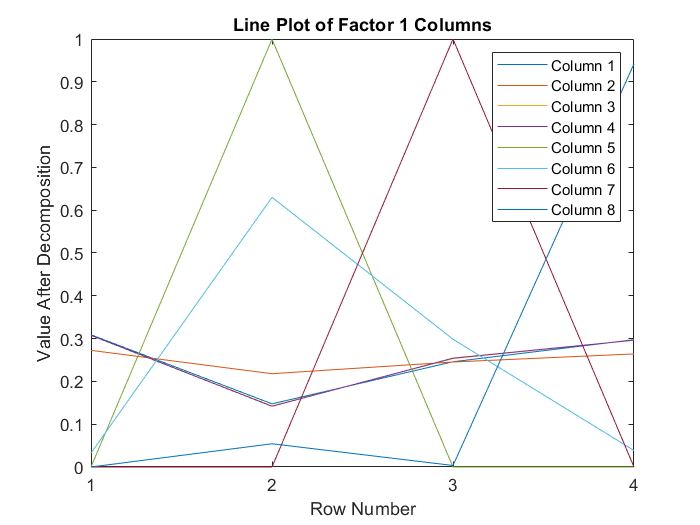

figure(3)
plot(factor3(:, 1), 'DisplayName', 'Column 1')
hold on
for column = 2:8
    plot(factor3(:, column), 'DisplayName', ('Column ' + string(column)))
end
hold off
title('Line Plot of Factor 3 Columns')
xlabel('Row Number')
xticks([42, 84, 126, 168, 210, 252, 294, 336, 378, 420])
ylabel('Value After Decomposition (log scale)')
legend('Location', 'southwest')

saveas(figure(1), 'Math398/images/CPT images/factor1matlab.png')

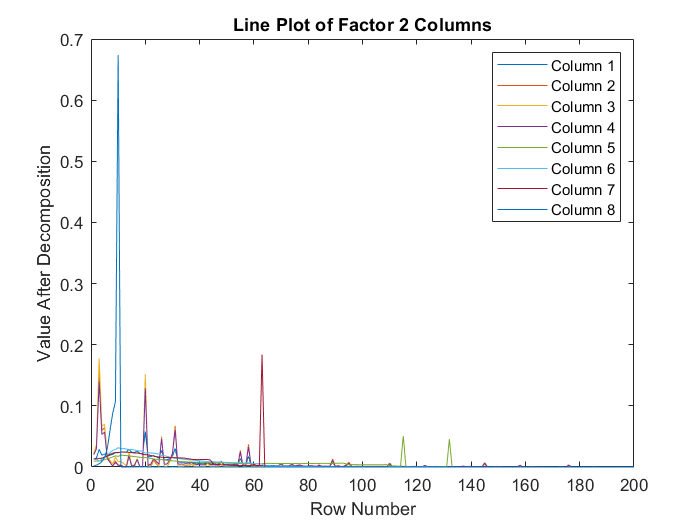

saveas(figure(2), 'Math398/images/CPT images/factor2matlab.png')

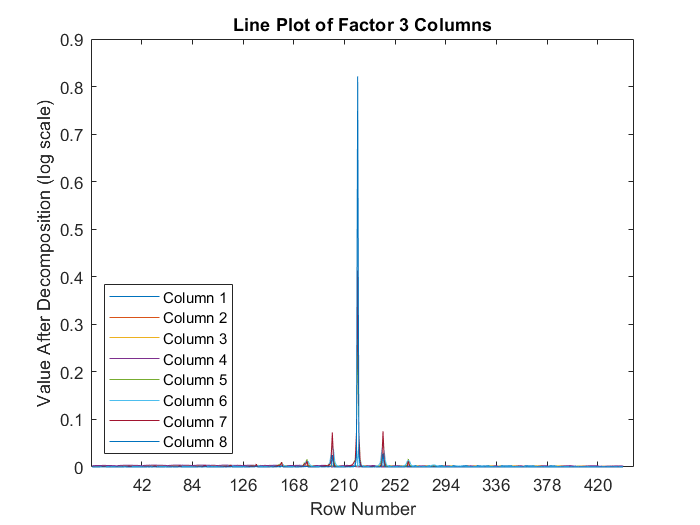

saveas(figure(3), 'Math398/images/CPT images/factor3matlab.png')